# Constellation Modeling with the Orbit Propagator Block

This example shows how to propagate the orbits of a constellation of satellites and compute and visualize access intervals between the individual satellites and several ground stations. It uses:

- Aerospace Blockset `Orbit Propagator` block

- Aerospace Toolbox `satelliteScenario` object

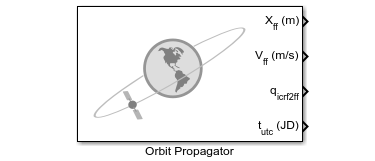

The Aerospace Toolbox `satelliteScenario` object lets you load previously generated, time-stamped ephemeris data into a scenario from a timeseries or timetable object. Data is interpolated in the scenario object to align with the scenario time steps, allowing you to incorporate data generated in a Simulink model into either a new or existing `satelliteScenario` object. This example shows how to propagate a constellation of satellites in Simulink with the Aerospace Blockset `Orbit Propagator` block, and load the logged ephemeris data into a `satelliteScenario` object for access analysis.

## Define Mission Parameters and Constellation Initial Conditions

Specify a start date and duration for the mission. This example uses MATLAB structures to organize mission data. These structures make accessing data later in the example more intuitive. They also help declutter the global base workspace. 

mission.StartDate = datetime(2020, 11, 30, 22, 23, 24);
mission.Duration  = hours(24);

The constellation in this example is a Walker-Delta constellation modeled similar to the ESA Galileo GNSS (Global navigation satellite system) constellation. The constellation consists of 24 satellites in medium Earth orbit (MEO). 

Walker-Delta constellations use the notation:

    
$$i:T/P/F$$


    where

    $i=$ inclination

    $T=$ total number of satellites

    $P=$ number of equally space geometric planes

    $F=$ spacing between satellites in adjacent planes

Walker-Delta constellations are a common solution for maximizing geometric coverage over Earth while minimizing the number of satellites required to perform the mission. The Galileo navigation system is a Walker-Delta ${56}^{\circ } :24/3/1$ constellation (24 satellites in 3 planes inclined at 56 degrees) in a 23,222 km orbit.

Specify Keplerian orbital elements for the constellation at `mission.StartDate`.

mission.Satellites.SemiMajorAxis  = 23222e3 * ones(24,1); % meters
mission.Satellites.Eccentricity   = 0.0005  * ones(24,1);
mission.Satellites.Inclination    = 56      * ones(24,1); % deg
mission.Satellites.ArgOfPeriapsis = 350     * ones(24,1); % deg

The ascending nodes of the orbital planes of a Walker-Delta constellation are uniformly distributed at intervals of $\frac{{360}^{\circ } }{P}$ around the equator. The number of satellites per plane, S, is given as $S=\frac{T}{P}$.  With 24 satellites total, this results in 3 planes of 8 satellites at 120 degree intervals around the equator. The satellites in each orbital plane are distributed at intervals of $\frac{{360}^{\circ } }{S}$, or 45 degrees.

mission.Satellites.RAAN               = sort(repmat([0 120 240], 1,8))'; % deg
mission.Satellites.TrueAnomaly        = repmat(0:45:315, 1,3)'; % deg

Lastly, account for the relative angular shift between adjacent orbital planes.  The phase difference is given as $\Delta \phi =F*\frac{360}{T}$, or 15 degrees in this case.

mission.Satellites.TrueAnomaly(9:16)  = mission.Satellites.TrueAnomaly(9:16)  + 15;
mission.Satellites.TrueAnomaly(17:24) = mission.Satellites.TrueAnomaly(17:24) + 30;

Show the constellation nodes in a table.

ConstellationDefinition = table(mission.Satellites.SemiMajorAxis, ...
    mission.Satellites.Eccentricity, ...
    mission.Satellites.Inclination, ...
    mission.Satellites.RAAN, ...
    mission.Satellites.ArgOfPeriapsis, ...
    mission.Satellites.TrueAnomaly, ...
    'VariableNames', ["a (m)", "e", "i (deg)", "Ω (deg)", "ω (deg)", "ν (deg)"])

## Open and Configure the Orbit Propagation Model

Open the included Simulink model. This model contains an `Orbit Propagator` block connected to output ports. The` Orbit Propagator` block supports vectorization. This allows you to model multiple satellites in a single block by specifying arrays of initial conditions in the `Block Parameters` window or using `set_param`. The model also includes a "Mission Analysis and Visualization" section that contains a dashboard `Callback button`. When clicked, this button runs the model, creates a new satelliteScenario object in the global base workspace containing the satellite or constellation defined in the `Orbit Propagator` block, and opens a Satellite Scenario Viewer window for the new scenario. To view the source code for this action, double click the callback button. **The "Mission Analysis and Visualization" section is a standalone workflow to create a new satelliteScenario object and is not used as part of this written example.**

mission.mdl = "OrbitPropagatorBlockExampleModel";
open_system(mission.mdl);
snapshotModel(mission.mdl);

Define the path to the `Orbit Propagator` block in the model.

mission.Satellites.blk = mission.mdl + "/Orbit Propagator";

Set satellite initial conditions. To assign the Keplerian orbital element set defined in the previous section, use `set_param`.

set_param(mission.Satellites.blk, ...
    "startDate",      num2str(juliandate(mission.StartDate)), ...
    "stateFormatNum", "Orbital elements", ...
    "orbitType",      "Keplerian", ...
    "semiMajorAxis",  "mission.Satellites.SemiMajorAxis", ...
    "eccentricity",   "mission.Satellites.Eccentricity", ...
    "inclination",    "mission.Satellites.Inclination", ...
    "raan",           "mission.Satellites.RAAN", ...
    "argPeriapsis",   "mission.Satellites.ArgOfPeriapsis", ...
    "trueAnomaly",    "mission.Satellites.TrueAnomaly");

Set the position and velocity output ports of the block to use the Earth-centered Earth-fixed frame, which is the International Terrestrial Reference Frame (ITRF).

set_param(mission.Satellites.blk, ...
    "centralBody",  "Earth", ...
    "outportFrame", "Fixed-frame");

Configure the propagator. This example uses the `Oblate ellipsoid (J2)` propagator which includes second order zonal harmonic perturbations in the satellite trajectory calculations, accounting for the oblateness of Earth.

set_param(mission.Satellites.blk, ...
    "propagator",   "Numerical (high precision)", ...
    "gravityModel", "Oblate ellipsoid (J2)", ...
    "useEOPs",      "off");

 Apply model-level solver setting using `set_param`.  For best performance and accuracy when using a numerical propagator, use a variable-step solver.

set_param(mission.mdl, ...
    "SolverType", "Variable-step", ...
    "SolverName", "VariableStepAuto", ...
    "RelTol",     "1e-6", ...
    "AbsTol",     "1e-7", ...
    "StopTime",   string(seconds(mission.Duration)));

 Save model output port data as a dataset of time series objects.

set_param(mission.mdl, ...
    "SaveOutput", "on", ...
    "OutputSaveName", "yout", ...
    "SaveFormat", "Dataset");

## Run the Model and Collect Satellite Ephemerides

Simulate the model.

mission.SimOutput = sim(mission.mdl);

Extract position and velocity data from the model output data structure.

mission.Satellites.TimeseriesPosECEF = mission.SimOutput.yout{1}.Values;
mission.Satellites.TimeseriesVelECEF = mission.SimOutput.yout{2}.Values;

Set the start data from the mission in the timeseries object.

mission.Satellites.TimeseriesPosECEF.TimeInfo.StartDate = mission.StartDate;
mission.Satellites.TimeseriesVelECEF.TimeInfo.StartDate = mission.StartDate;

The timeseries objects contain position and velocity data for all 24 satellites.

mission.Satellites.TimeseriesPosECEF

## Load the Satellite Ephemerides into a `satelliteScenario O`bject

Create a satellite scenario object for the analysis.

scenario = satelliteScenario(mission.StartDate, mission.StartDate + hours(24), 60);

Add all 24 satellites to the satellite scenario from the ECEF position and velocity timeseries objects using the `satellite` method.

sat = satellite(scenario, mission.Satellites.TimeseriesPosECEF, mission.Satellites.TimeseriesVelECEF, ...
    "CoordinateFrame", "ecef", "Name", "GALILEO " + (1:24))
disp(scenario)

## Set Graphical Properties on the Satellites

Viewer windows with many satellites can become crowded and difficult to read. To keep the window readable, we manually control graphical properties of the scenario elements.

Hide the satellite labels and ground tracks. 

set(sat, "ShowLabel", false);
hide([sat(:).GroundTrack]);

 Set satellites in each orbital plane to have the same orbit color.

set(sat(1:8), "MarkerColor", "red");
set(sat(9:16), "MarkerColor", "blue");
set(sat(17:24), "MarkerColor", "green");
orbit = [sat(:).Orbit];
set(orbit(1:8), "LineColor", "red");
set(orbit(9:16), "LineColor", "blue");
set(orbit(17:24), "LineColor", "green");

## Add Ground Stations to Scenario

To provide accurate positioning data, a location on Earth must have access to at least 4 satellites in the constellation at any given time. In this example, use three MathWorks locations to compare total constellation access over the 1 day analysis window to different regions of Earth:

- MathWorks headquarters in Natick, Massachusetts, USA (42.30048**°**, -71.34908**°**)

- MathWorks München in Ismaning (near München), Germany (48.23206**°**, 11.68445**°**)

- MathWorks Bangalore in Bangalore, India (12.94448**°**, 77.69256**°**)

gsUS = groundStation(scenario, 42.30048, -71.34908, ...
    "MinElevationAngle", 10, "Name", "MW Natick");
gsDE = groundStation(scenario, 48.23206, 11.68445, ...
    "MinElevationAngle", 10, "Name", "MW Munchen");
gsIN = groundStation(scenario, 12.94448, 77.69256, ...
    "MinElevationAngle", 10, "Name", "MW Bangalore");

figure
geoscatter([gsUS.Latitude gsDE.Latitude gsIN.Latitude], ...
    [gsUS.Longitude gsDE.Longitude gsIN.Longitude], "red", "filled")
geolimits([-75 75], [-180 180])
title("MathWorks Ground Stations")

## Compute Ground Station to Satellite Access (Line-of-Sight Visibility)

Calculate line-of-sight access between the ground stations and each individual satellite using the `access` method.

for idx = 1:numel(sat)
    access(gsUS, sat(idx));
    access(gsDE, sat(idx));
    access(gsIN, sat(idx));
end
accessUS = [gsUS(:).Accesses];
accessDE = [gsDE(:).Accesses];
accessIN = [gsIN(:).Accesses];

Set access colors to match orbital plane colors assigned earlier in the example.

set(accessUS(1:8), "LineColor", "red");
set(accessUS(9:16), "LineColor", "blue");
set(accessUS(17:24), "LineColor", "green");

set(accessDE(1:8), "LineColor", "red");
set(accessDE(9:16), "LineColor", "blue");
set(accessDE(17:24), "LineColor", "green");

set(accessIN(1:8), "LineColor", "red");
set(accessIN(9:16), "LineColor", "blue");
set(accessIN(17:24), "LineColor", "green");

View the full access table between each ground station and all satellites in the constellation as tables. Sort the access intervals by interval start time. Satellites added from ephemeris data do not display values for StartOrbit and Stop orbit.

intervalsUS = accessIntervals(accessUS);
intervalsUS = sortrows(intervalsUS, "StartTime", "ascend")
intervalsDE = accessIntervals(accessDE);
intervalsDE = sortrows(intervalsDE, "StartTime", "ascend")
intervalsIN = accessIntervals(accessIN);
intervalsIN = sortrows(intervalsIN, "StartTime", "ascend")

## View the Satellite Scenario

 Open a 2-D and 3-D viewer window of the scenario.  The viewer window contains all 24 satellites in each of the three orbital planes as well as the three ground stations defined earlier in this example. A line is drawn between each ground station and satellite during the their corresponding access intervals.

viewer3D = satelliteScenarioViewer(scenario);

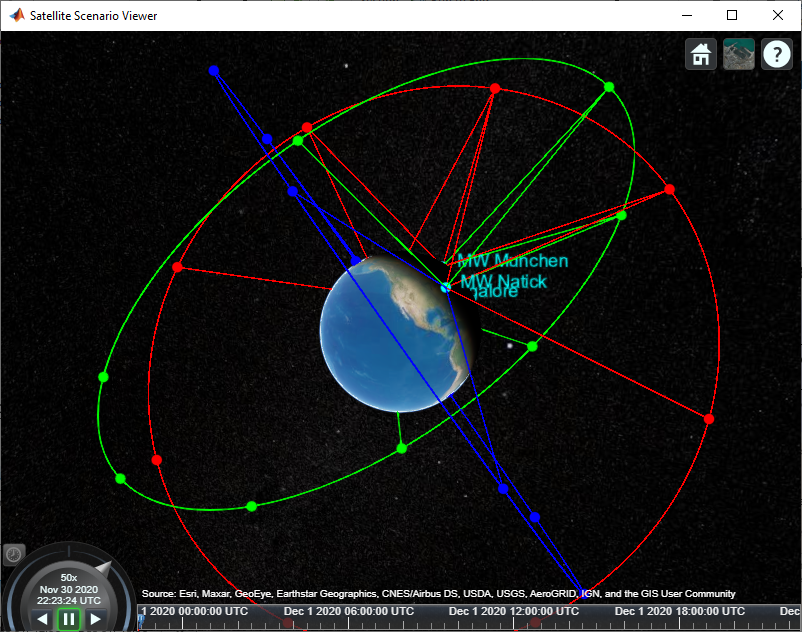

## Compare Access Between Ground Stations

Calculate access status between each satellite and ground station using the accessStatus method.  Plot cumulative access for each ground station over the 1 day analysis window.

% Initialize array with size equal to number of timesteps in scenario
timeSteps = mission.StartDate:seconds(60):mission.StartDate+days(1);
statusUS = zeros(1, numel(timeSteps));
statusDE = statusUS;
statusIN = statusUS;

% Sum cumulative access at each timestep
for idx = 1:24
    statusUS = statusUS + accessStatus(accessUS(idx));
    statusDE = statusDE + accessStatus(accessDE(idx));
    statusIN = statusIN + accessStatus(accessIN(idx));
end
clear idx;

subplot(3,1,1);
plot(timeSteps, statusUS);
title("MW Natick to GALILEO")
ylabel("# of satellites")
subplot(3,1,2);
plot(timeSteps, statusDE);
title("MW München to GALILEO")
ylabel("# of satellites")
subplot(3,1,3);
plot(timeSteps, statusIN);
title("MW Bangalore to GALILEO")
ylabel("# of satellites")

Collect access interval metrics for each ground station in a table for comparison.

statusTable = [table(height(intervalsUS), height(intervalsDE), height(intervalsIN)); ...
    table(sum(intervalsUS.Duration)/3600, sum(intervalsDE.Duration)/3600, sum(intervalsIN.Duration)/3600); ...
    table(mean(intervalsUS.Duration/60), mean(intervalsDE.Duration/60), mean(intervalsIN.Duration/60)); ...
    table(mean(statusUS, 2), mean(statusDE, 2), mean(statusIN, 2)); ...
    table(min(statusUS), min(statusDE), min(statusIN)); ...
    table(max(statusUS), max(statusDE), max(statusIN))];
statusTable.Properties.VariableNames = ["MW Natick", "MW München", "MW Bangalore"];
statusTable.Properties.RowNames = ["Total # of intervals", "Total interval time (hrs)",...
    "Mean interval length (min)", "Mean # of satellites in view", ...
    "Min # of satellites in view", "Max # of satellites in view"];
statusTable

Walker-Delta constellations are evenly distributed across longitudes.  Natick and München are located at similar latitudes, and therefore have very similar access characteristics with respect to the constellation.  Bangalore is at a latitude closer to the equator, and despite having a lower number of individual access intervals, it has the highest average number of satellites in view, the highest overall interval time, and the longest average interval duration (by 40 minutes).  All locations always have a minimum of 4 satellites in view, as is required for GNSS trilateration.

## References

[1] Wertz, James R, David F. Everett, and Jeffery J. Puschell. *Space Mission Engineering: The New Smad*. Hawthorne, CA: Microcosm Press, 2011. Print.

[2] Beech, Theresa W., Sefania Cornana, Miguel B. Mora. *A Study of Three Satellite Constellation Design Algorithms. *14th International Symposium on Space Flight Dynamics, Foz do Iguaçu, Brazil 1999.

[3] The European Space Agency: Galileo Facts and Figures. https://www.esa.int/Applications/Navigation/Galileo/Facts_and_figures

*Copyright 2020 The MathWorks, Inc.*